#  CBCT Reconstruction Pipeline: FDK → IR → DL Refinement

This Live Script demonstrates a complete cone‑beam CT (CBCT) reconstruction workflow using three stages:

- **FDK Reconstruction** – classical analytical Feldkamp–Davis–Kress method

- **Iterative Reconstruction (IR)** – noise‑reduced refinement from sparse/noisy projections

- **Deep-Learning Reconstruction (DL)** – learned enhancement model for high‑quality output

Each stage takes the output of the previous step, enabling a clean, modular pipeline.

**CBCT Raw Projection Dataset**

This example uses a Cone‑Beam CT (CBCT) raw projection dataset provided as MathWorks support files. The dataset contains projection data required to demonstrate CBCT reconstruction workflows, including FDK and iterative reconstruction methods.

The dataset is automatically downloaded from the MathWorks support files server using the script below. The data is saved under a local folder named `CBCTdata` in the current working directory and unzipped for direct use in the reconstruction examples

**Please note:*** The original CBCT projection data is sized ****2752 × 320 × 360****, based on a reference Canon CT detector. For demonstration and example purposes, the data has been adjusted to ****600 × 360 × 360****.*

***Dataset source:***

[Dataset](https://ssd.mathworks.com/supportfiles/medical/CBCT_raw_data.zip)

dataDir = fullfile(pwd, "CBCTdata","CBCT_raw_data");
inputData= "CBCT_lowDose_Projections.mat";

[FDK] Filtering 360 views with GPU FFT ...
[FDK] nu=600 nv=600 V=360 | nx=600 ny=600 nz=360 | du=0.688 dv=0.267 | dx=0.500 dy=0.500 dz=0.500 | u0=300.109 v0=300.938 | GPU=1



projectionData = fullfile(dataDir, inputData)

## 1️⃣ FDK Reconstruction

*Analytical Cone-Beam CT Reconstruction*

The **Feldkamp–Davis–Kress (FDK)** algorithm is the classical analytic method used for circular CBCT trajectories. It is fast and provides a good baseline reconstruction, especially when projections are not too sparse.

**Purpose:**

- Ramp-filter projections

- Perform geometric backprojection

- Produce an initial 3‑D volume reconstruction

volFDK = reconFDK(projectionData, 'Verbose', true);

**Output:**

- volFDK — reconstructed 3‑D volume (typically single precision)

- Useful as a baseline for further enhancement via IR or DL methods

## 2️⃣ Iterative Reconstruction (IR)

*Physics-Based Noise Reduction and Artifact Suppression*

Iterative reconstruction incorporates a forward model and regularization (e.g., TV, edge-preserving penalties).

It typically improves:

- Low-dose or sparse-view reconstructions

- Streak artifacts

- Noise characteristics

- Edge sharpness

**Inputs:**

- The original projection data (projectionData)

- The analytic FDK reconstruction (volFDK)

[IR] Start | UseGPU=true | nx=600 ny=600 nz=360 | nu=600 nv=600 | du=0.688 dv=0.688 | dx=0.500 dy=0.500 dz=1.000
Iter 1/1 | ||res||_2 = 1.571e+04


volHIR = reconIR(projectionData,volFDK, 'Verbose', true);

## 3️⃣ Deep-Learning Reconstruction (DL)

*Learned Hybrid Enhancement (FDK → IR → DL)*

This stage applies a trained neural network that learns to map:

**FDK → Iterative Reconstruction (IR) quality**

The DL model captures subtle structures and removes residual artifacts that physics-only IR cannot.

**Inputs:**

- volFDK: Contains the baseline FDK reconstruction

- `volHIR`: Contains the improved IR reconstruction (target)


=== Shape Debug ===
Mode: FULL-SLICE
Original:  [600 600]
Padded:    [608 608]
Net input: [608 608 1]

Selected 72 validation slices (requested 72). Median raw-std=0.00144, min raw-std in val=0.000139, median cov=0.149
Train selection: kept 169 / 288 non-val slices (58.7%)
Train X:[0.0000 1.0000] Y:[0.0000 1.0000]
Val   X:[0.0000 1.0000] Y:[0.0000 1.0000]
Raw RMSE: train=0.0990 | val=0.0579

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       478.81 |       411.27 |  11

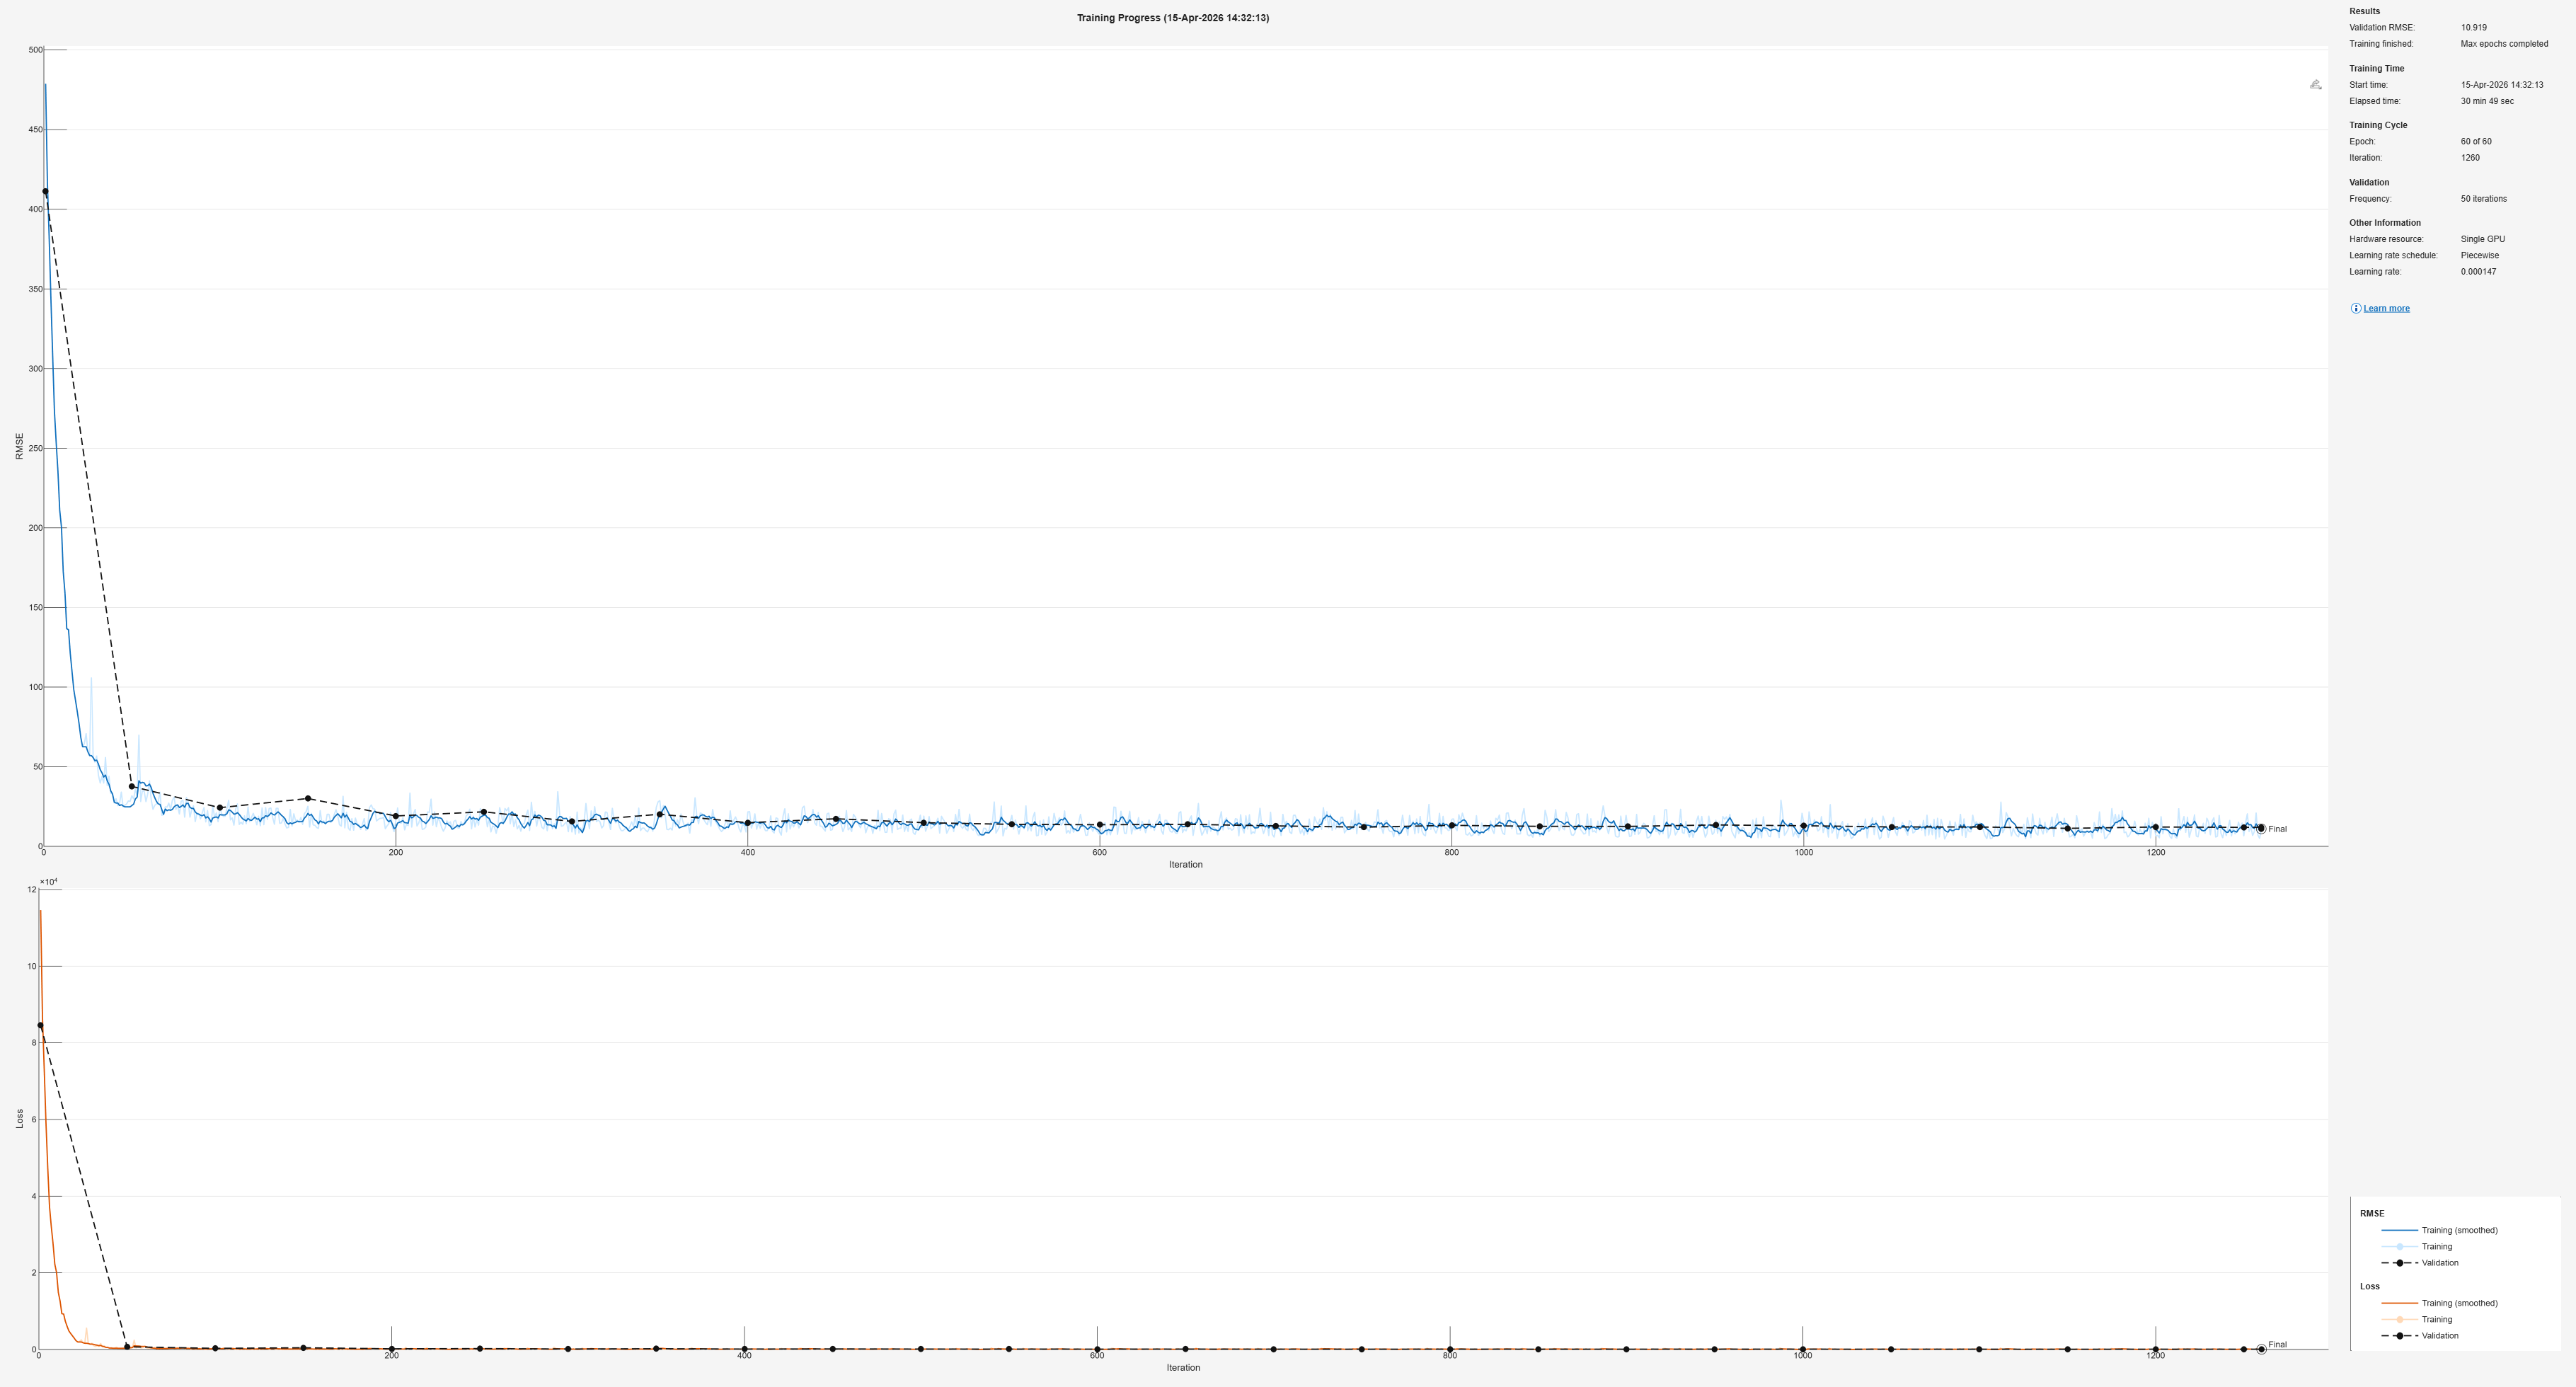

Validation: PSNR=38.63 dB | SSIM=0.9839 (N=72)

Prediction complete ✔  Saved to: /OneDrive/02_Projects/Account_Project/2025_CT_Project/main/gecatsim/Scripts/01_CT_Example_Scripts/cbct_run_mid/dl_recon_3d.mat


[volDL, ~, ~] = reconDL(volFDK, volHIR, 'Verbose', true);

**Output:**

- volDL — improved reconstruction with reduced noise and streak artifacts

- Often used as the target reference for training DL models

## 🔚 Summary of the Pipeline

Together, these methods provide a complete and modular reconstruction chain suitable for:

- Sparse-view CBCT

- Low-dose scans

- Research prototyping

- DL training/evaluation workflow

# 4. Visualization and Hounsfield Unit Mapping

This section converts the reconstructed CBCT volume into **Hounsfield Units (HU)** and visualizes it using MATLAB’s **Medical Imaging Toolbox**. The workflow includes:

- Deriving HU calibration (air/water reference)

- Creating a `medicalVolume` with correct voxel geometry

- Performing smoothing and window/level adjustments

- Using `volshow` with cinematic rendering for high‑quality 3‑D visualization

## 4.1 Converting Reconstruction Output to Hounsfield Units (HU)

CBCT systems typically output arbitrary reconstruction units. To bring your volume into a **clinically meaningful scale**, we map:

- **Air → –1000 HU**

- **Water → 0 HU**

Because not all datasets provide calibration masks, we use an **intensity percentile estimate** (1st and 99th percentiles) as approximate references.

% === Inputs ===
reconImage = double(volFDK);     % ensure double for math

p = [1 99];
prc = prctile(reconImage(:), p);
airVal   = prc(1);   % rough "air-like" signal
waterVal = prc(2);   % rough "water-like" signal

% Safety checks
if ~isfinite(airVal) || ~isfinite(waterVal)
    error('Non-finite air/water reference values. Check reconImage or masks.');
end
if abs(waterVal - airVal) < eps
    error('airVal and waterVal are too close. Provide better references/ROIs.');
end

% Linear HU mapping: air → -1000 HU, water → 0 HU
slope     = 1000 / (waterVal - airVal);
intercept = -1000 - slope * airVal;

% Compute HU, handle NaNs gracefully
volumeHU = slope * reconImage + intercept;
volumeHU(~isfinite(volumeHU)) = NaN;

% Optional: clip to a reasonable HU range
clipRange = [-1200, 3000];
volumeHU = min(max(volumeHU, clipRange(1)), clipRange(2));

% Cast to int16
volumeHU_int16 = int16(round(volumeHU));

## 4.2 Creating a Medical Imaging Toolbox Volume

To visualize using cinematic rendering, we create a `medicalVolume` object that includes voxel spacing and a patient‑compatible coordinate system (LPS+).

% === Medical Imaging Toolbox: geometry and patient coordinate system ===
R = medicalref3d(size(volumeHU_int16));
% Create medical volume and set patient coordinate system
medVolReconImage = medicalVolume(volumeHU_int16, R);
medVolReconImage.VolumeGeometry.PatientCoordinateSystem = "LPS+";
% Optional sanity prints
fprintf('HU mapping: slope=%.6f, intercept=%.6f\n', slope, intercept);
fprintf('AirVal=%.6g → -1000 HU, WaterVal=%.6g → 0 HU\n', airVal, waterVal);

This ensures:

- Consistent spatial scaling

- Correct anatomical orientation

- Compatibility with clinical visualization workflows

% Given: slope = 1171.154553; intercept = -1036.589915;
volHU = slope* medVolReconImage.Voxels + intercept;

volHU_clean = imgaussfilt3(volHU, 1.5);
alpha = zeros(256,1);
alpha(120:256) = linspace(0,1,137);
voltemp = volshow(volHU_clean, ...
    RenderingStyle="CinematicRendering", ...
    Colormap=bone(256), ...
    DisplayRange=[50 1800], ...   % bone window
    Alphamap=alpha);  % soft tissue→transparent, bone→opaque
viewer = voltemp.Parent;
viewer.BackgroundColor = [0 0.2 0.6];

V = medVolReconImage.Voxels;        % int16 HU, oriented
[H,W,Z] = size(V);
i = round(W/2);                 % sagittal index (x)

HU mapping: slope=181790.604252, intercept=-850.555108


j = round(H/2);                 % coronal  index (y)

AirVal=-0.000822072 → -1000 HU, WaterVal=0.00467876 → 0 HU


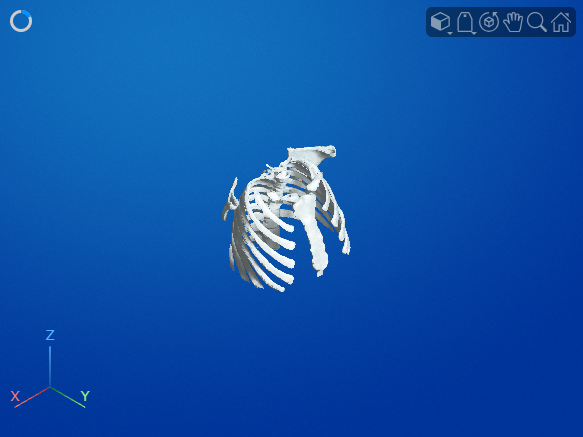

k = round(Z/2);                 % axial    index (z)
% --- AXIAL (you said this needed upside-down fix earlier) ---
Axial = V(:,:,k);      % if you already flipped the whole volume, remove this
Axial = rot90(Axial, 2); 
%Axial=fliplr(Axial);

% --- SAGITTAL (rotate 180°) ---
Sagittal = squeeze(V(:, i, :)); % [H x Z]
Sagittal = rot90(Sagittal, 1);  % 180° rotation
Sagittal=fliplr(Sagittal);

% --- CORONAL (rotate 180°) ---
Coronal = squeeze(V(j, :, :));  % [W x Z]
Coronal = rot90(Coronal, 1);    % 180° rotation
% (equivalently: Coronal = flipud(fliplr(Coronal));)


figure('Color','k');
tiledlayout(1,3,'Padding','compact','TileSpacing','compact');
nexttile; imshow(Axial,[]);    title('Axial','Color','w');
nexttile; imshow(Sagittal,[]); title('Sagittal','Color','w');
nexttile; imshow(Coronal,[]);  title('Coronal','Color','w');

##  Summary of Visualization Stage

- Convert reconstruction intensities → **Hounsfield Units**

- Build a **medicalVolume** with correct voxel spacing

- Smooth the data for clean cinematic appearance

- Visualize using `volshow` with full control over shading, color, and opacity

This creates a professional, radiology-grade rendering of your reconstructed CBCT volume.

# ⚡ 5. CUDA Code Generation & GPU-Accelerated Visualization

This section shows how to **generate CUDA code** for the FDK reconstructor using **GPU Coder**, build a **CUDA MEX**, run it on your **600×600×360** dataset, and then **visualize** the reconstructed volume. The FFT filtering is mapped to **cuFFT** in the generated MEX, while backprojection runs on CPU (as designed).

## 5.1 Generate CUDA MEX with GPU Coder

We first configure GPU Coder, specify **fixed input sizes** (for maximum performance), and compile the entry point `reconFDK_codegen` into a CUDA MEX.

cfg = coder.gpuConfig('mex');
cfg.GenerateReport = true;


**Notes:**

- Use `'mex'` for rapid iteration in MATLAB; switch to `'lib'` for a **CUDA library** to integrate elsewhere.

- `Nf_fftConst = int32(2048)` corresponds to `nu=600`, `padFactor=2` → `2^nextpow2(1200)=2048`.

- If you change `nu` or `padFactor`, update `Nf_fftConst` and rebuild.

## 5.2 Run the CUDA MEX on Your CBCT Data

Load your `.mat` inputs, match types/shapes, and call the generated MEX. This will perform **GPU-accelerated FFT filtering** via cuFFT and reconstruct the 3‑D volume.

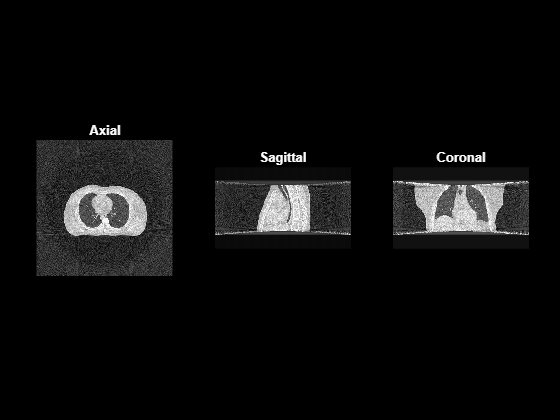

%% Load & prep inputs
S = load(projectionData);

P          = single(S.P);                       % [nu,nv,nViews] e.g., [600,600,360]
angles_rad = single(S.angles_rad(:).');         % [1,nViews] row
DSD        = single(S.DSD);  DSO = single(S.DSO);
du         = single(S.du);   dv  = single(S.dv);
u0         = single(S.u0_pixels); v0 = single(S.v0_pixels);

% Recon grid (example: 0.5 mm voxels → 300×300×180 mm => 600×600×360)
dx = single(0.5); dy = single(0.5); dz = single(0.5);
nx = int32(600);  ny = int32(600);  nz = int32(360);

% Controls (memory-safe choices)
filter_type = 'ramp';         % 'ramp' | 'hamming' | 'shepp-logan'
Nf_fft      = int32(1024);    % >= nu ; power-of-two suggested
padFactor   = single(1);      % informational (Nf_fft dictates effective FFT length)
batchZ      = int32(32);       % smaller → less memory (e.g., 8 or 16)

useGPU      = true;           % MEX: cuFFT used automatically; false to test CPU path
verbose     = false;

inputs = { ...
    P, angles_rad, DSD, DSO, du, dv, u0, v0, ...
    dx, dy, dz, ...
    padFactor,   ...
    };

codegen -config cfg -args inputs reconFDK_codegen

tic
cuFDKvol = reconFDK_codegen_mex(inputs{:});
toc

# 5.3 Visualize the Reconstructed CBCT Volume

After reconstructing the 3D CBCT volume using the CUDA‑accelerated MEX function, we can visualize the results to inspect the image quality and anatomical structures. MATLAB provides several convenient tools for interactive volume exploration.

A simple and effective option is to use `sliceViewer`, which allows you to scroll through axial, sagittal, or coronal slices. The viewer can be launched directly with the reconstructed volume:

fig = uifigure('Name','CBCT Visualization');
panel = uipanel(fig, 'Position',[20 20 600 600]);

sliceViewer(cuFDKvol, 'Parent', panel, 'Colormap', gray);

# 5.4 Generate CUDA MEX with GPU Coder for HIR and DL methods

#### Cuda code generation for **Hybrid Iterative Reconstruction (HIR)**  method

**CBCT Reconstruction using HIR mex file**

% Load inputs
S    = load(projectionData);
%FDK  = volFDK;      % contains FDKvol (single)

P           = single(S.P);                       % [nu,nv,nViews]
angles_rad  = single(S.angles_rad(:).');
DSD         = single(S.DSD);     DSO = single(S.DSO);
du          = single(S.du);      dv  = single(S.dv);
u0          = single(S.u0_pixels); v0 = single(S.v0_pixels);

x0          = single(volFDK);                % initial volume [nx,ny,nz]
[nx,ny,nz]  = size(x0);
dx = single(0.5); dy = single(0.5); dz = single(0.5);  % or from metadata

% IR hyperparameters

numIter    = int32(1);
alpha      = single(0.05);

Code generation successful: View report



lambda     = single(0.03);
gaussSigma = single(1.5);
step = single(1.0);   % instead of ~0.5


Elapsed time is 6.712475 seconds.


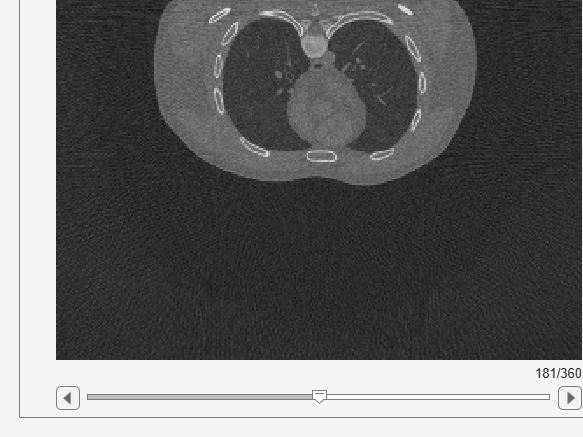

% Backproj/filter controls
padFactor   = single(1.0);        % Nf_eff controlled inside FDK (uses 1024)
batchZ      = int32(16);

% Forward projector controls
numSamples  = int32(32);
batchPixels = int32(256*1024);


useGPU      = true;               % cuFFT in backprojector
verbose     = true;

cfg = coder.gpuConfig('mex');
inputs = {...
    P, angles_rad, DSD, DSO, du, dv, u0, v0, ...
    dx, dy, dz, x0, ...
    numIter, alpha, lambda, gaussSigma, ...
    padFactor};

codegen -config cfg reconIR_codegen -args inputs

tic
cuIRvol = reconIR_codegen_mex(inputs{:});
toc

#### Cuda code generation for** Deep Learning (DL)**  method

cfg = coder.gpuConfig('mex');

cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');

% Input is a raw slice [H W] single (e.g., 600x600). Allow variable H/W up to 608.
Xtype = coder.typeof(single(0), [608 608], [true true]);   

codegen -config cfg reconDL_codegen.m -args {Xtype} -report

**CBCT Reconstruction using DL mex file**

% Load your raw volume (pre-FDK or FDK) that you used earlier
xFDK_raw = single(volFDK);            % adjust field name as needed

[H0,W0,Z] = size(xFDK_raw);
yPredVol = zeros([H0 W0 Z], 'single');

tic;
for k = 1:Z
    Xk = xFDK_raw(:,:,k);               % raw single slice [H0 W0]
    Ypad = myPredict_preproc_mex(Xk);   % does percentile->quantize->pad->predict
    yPredVol(:,:,k) = centerCropTo(Ypad, H0, W0);
end
t = toc;

fprintf('Inference (TIFF-equivalent preproc) done in %.3f s. [%d %d %d]\n', t, H0, W0, Z);
%save('dl_recon_3d.mat','yPredVol','-v7.3');


Code generation successful: View report



function Yc = centerCropTo(Ypad, Ht, Wt)
    H = size(Ypad,1); W = size(Ypad,2);
    sy = floor((H - Ht)/2) + 1;
    sx = floor((W - Wt)/2) + 1;

Elapsed time is 26.552546 seconds.


    Yc = Ypad(sy:sy+Ht-1, sx:sx+Wt-1);
end


Code generation successful: View report



Inference (TIFF-equivalent preproc) done in 53.377 s. [600 600 360]
